Project 3: Short-Time Fourier Analysis 

Exercises 3.1 

Carregando dados e configurando ambiente:

load('mcclellan/Data/s5.mat');
addpath('mcclellan/Functions/');
ncenter = [3750, 16100, 17200];
windowLengths = [401,201,101,51];
nfft = 512;


Plotando os três pontos sugeridos:

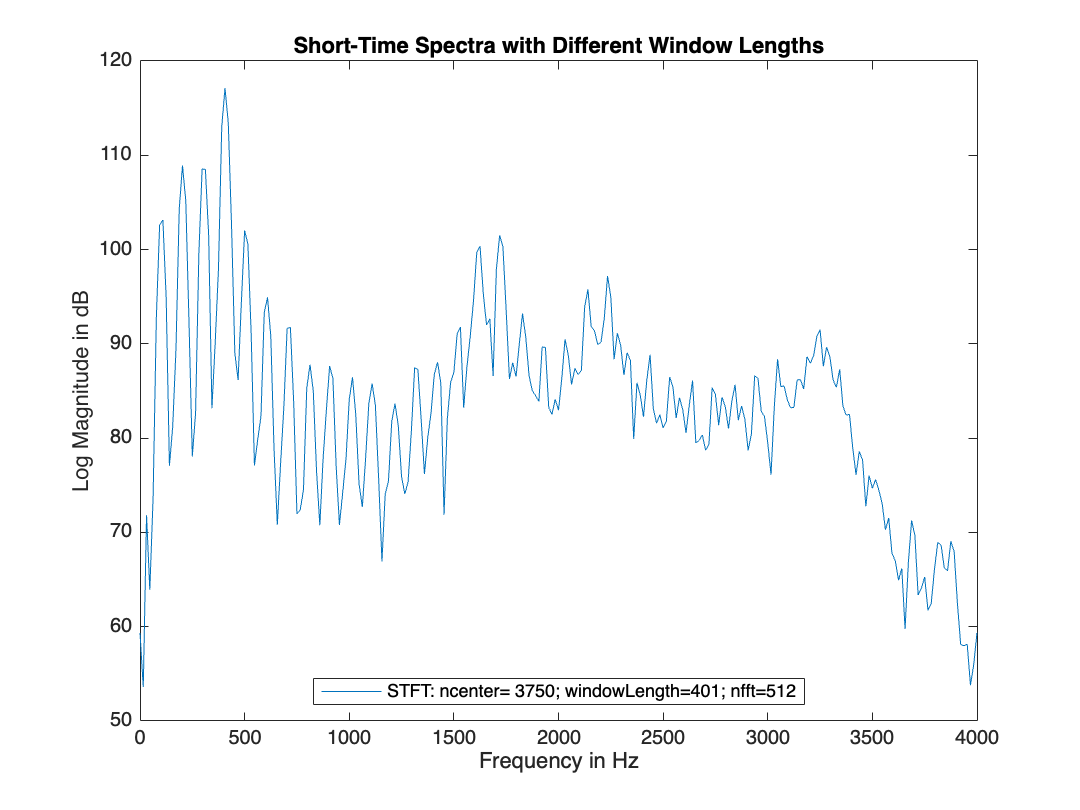

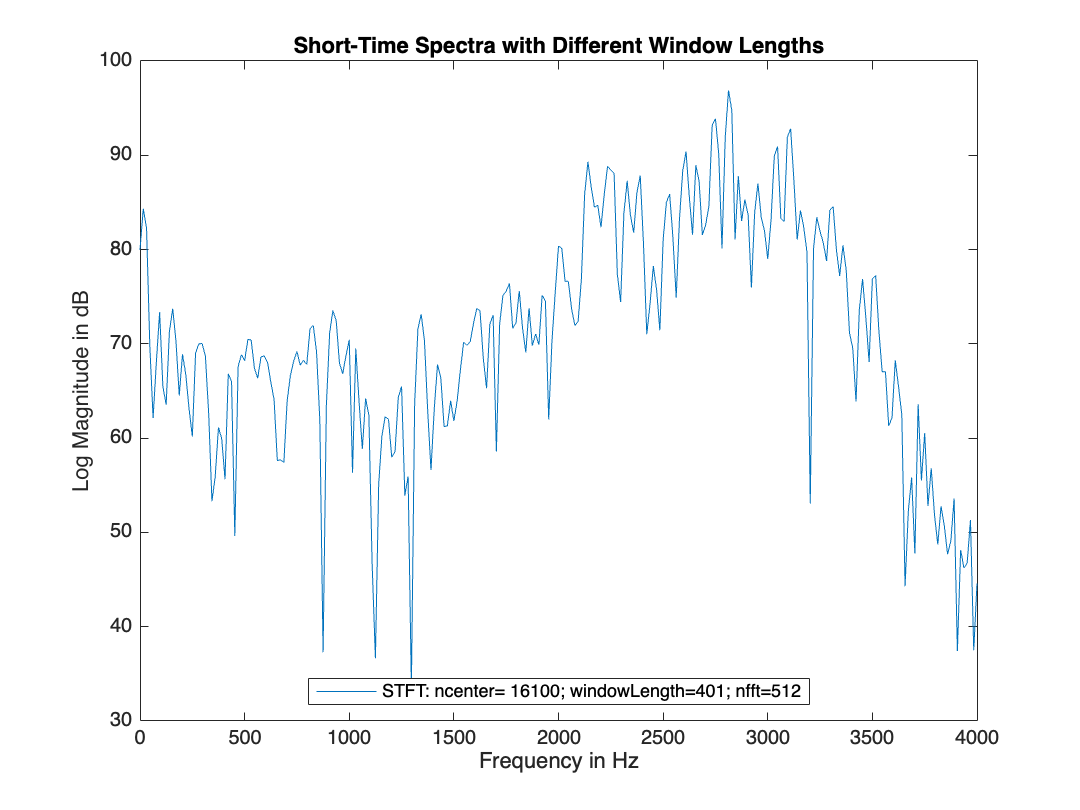

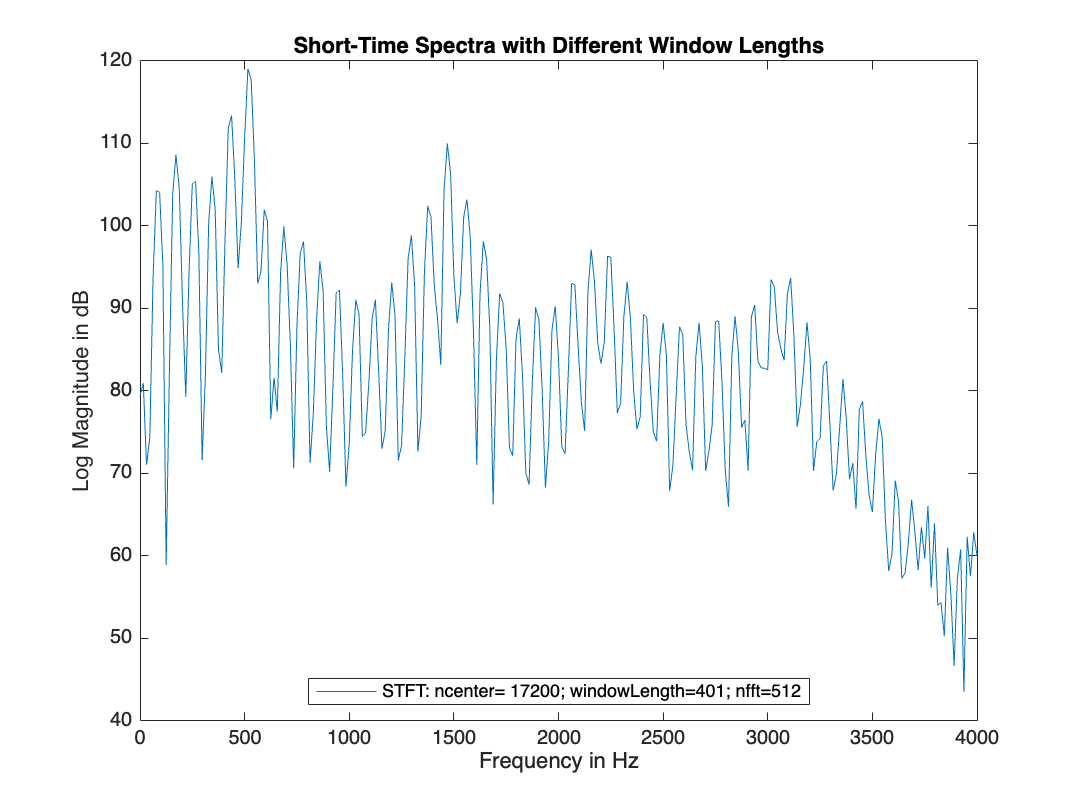

for i=1:1:3
    figure
    speccomp(s5,ncenter(i),windowLengths(1),nfft,0)
    str=sprintf('STFT: ncenter= %d; windowLength=%d; nfft=%d',ncenter(i),windowLengths(1),nfft);
    legend(str,'Location','south')
end 

Utilizando o primeiro ponto, vamos ver a diferença do espectro levando em conta a alteração do tamanho da janela. Com isso podemos ver a perda na resolução no domínio da frequência. Entretanto o janelamento com comprimentos menores nos permite avaliar com maior precisão a variação e variação das características espectrais do ponto de vista temporal. 

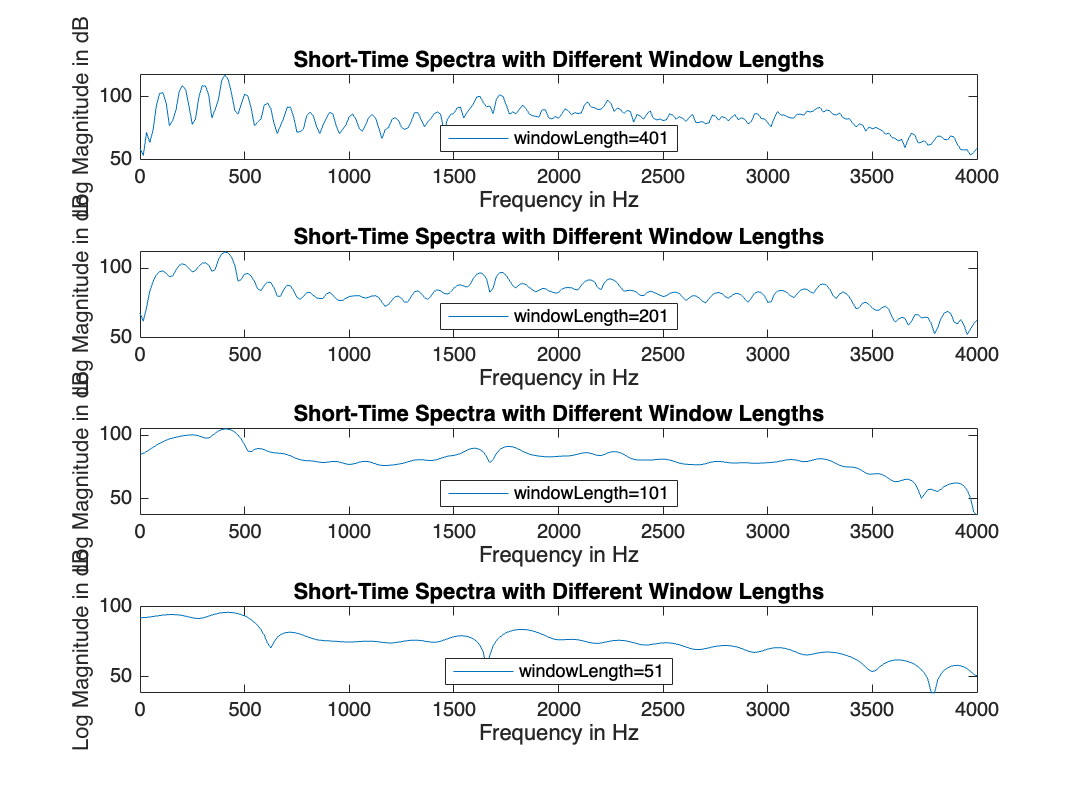

figure
for i=1:1:4
    subplot(4,1,i)
    speccomp(s5,ncenter(1),windowLengths(i),nfft,0)
    str=sprintf('windowLength=%d',windowLengths(i));
    legend(str,'Location','south')
end 